# RSA Encryption/Decryption of Multimedia

*EEE8119*

*Chris Hemingway, Yaw Mensah, Panukorn Wattanajung, Zheliang Geng, Xiaotian Han*

In this demonstration, we encrypt an image with RSA using both Electronic CodeBook (ECB) and Cipher Block Chaining (CBC) encryption.

Other functions in attached folder "matlab_rsa.zip" implement the RSA functionality, and should be referenced.

ls rsa_*.m

rsa_decrypt.m		rsa_encrypt.m		rsa_find_primes.m	rsa_keygen.m



## Pre-Requisites

Clear variables and command window. 

clc; clear;

Import a demo image. Use MATLAB built-in.

We are using a greyscale image, of size 256x256. Display to verify.

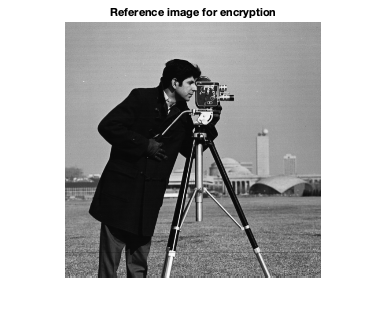

img = imread("cameraman.tif");
imshow(img);
title('Reference image for encryption');

disp(size(img)); %Get dimensions of image

   256   256



Our RSA library requires the [VariablePrecisionInteger library](https://uk.mathworks.com/matlabcentral/fileexchange/22725-variable-precision-integer-arithmetic) from John D'Errico. This allows us to use integers of length limited only by available memory.

Add this to the MATLAB search path.

addpath(['VariablePrecisionIntegers' filesep 'VariablePrecisionIntegers']);

We have defined functions to convert VariablePrecisionInteger's to/from text

ls *char*.m

char2vpi.m	vpi2char.m



## Key Generation

### Generate Primes

We need two prime numbers $p$ and $q$ to generate our keys.

Requirements are that they are of slightly different lengths, and that the product $n=p\times q$is exactly n_bits in length. 

We wrote a function rsa_find_primes to do this, which given a number of bits, returns two suitable primes. Note these are chosen at random, so the same number of bits may return different primes. 

To ensure the number of bits n_bits is correct, the first prime p is chosen by checking random numbers below $2^{\frac{n_\mathrm{bits}}{2}} \;$for primality. Once found, the number of bits of p is determined by $p_\mathrm{bits}=\mathrm{ceil}\left({\mathrm{log}}_{2\;} p\right)$.  the second prime q is determined by finding a prime number in the interval $2^{\frac{p_\mathrm{bits}-1}{2}} {+1\le q\le \;2}^{\frac{p_\mathrm{bits}}{2}} \;$. This ensures that $n‾_\mathrm{bits}\;=\;\mathrm{ceil}\left({\mathrm{log}}_{2\;} p\right)+\mathrm{ceil}\left({\mathrm{log}}_2 \;q\right)$.

#### Example Primes

The example below interactively chooses P and Q at random using our function, drag the slider to change the number of bits and note the product n is the correct size.

[p,q] = rsa_find_primes(28)

p = 8689

q = 22937

fprintf("p is prime? = %s \n", string(isprime(p)));

p is prime? = true 


fprintf("q is prime? = %s \n", string(isprime(q)));

q is prime? = true 


The total number of bits of the product $n=p\times \;q$ is

n=p*q;
fprintf("n=%d \t %s",n,dec2bin(n)); %both in decimal and binary

n=199299593 	 1011111000010001001000001001

fprintf("n is %d bits",length(dec2bin(n))); %Number of bits

n is 28 bits

Once we have our 2 prime numbers, we can generate the keys. This is done in the function rsa_keygen, which we will describe key features of here. Let's call it now, and time how long it takes for later.

[Kp, Ks] = rsa_keygen(48); %48 bit key as example
disp(Kp); disp(Ks);

    n: 2.1084e+14
    e: 5

    n: 2.1084e+14
    d: 1.6867e+14



Here we refer to the **public** key as $K_p$ and the **private** (secret) key as $K_s$

#### Public/Private Base n

disp (Kp.n);

   2.1084e+14



Our base $n=p*q$ is what is used in the modular exponentiation in both encryption and decryption, and is part of the public and private keys.

Note that the width of n in bits is commonly referred to as the **size** of our public/private key. This is a parameter we would like to specify, we chose **48 bits, **let's check that $n$ is actually this value.

ceil(log2(Kp.n))

ans = 48

The strength of RSA relies on it being slow to factorise $n$ into prime factors. For our simple 32 bit key, this can be done relatively quickly. Let's see how long it takes:

tic;
factor(Kp.n);
toc

Elapsed time is 0.259794 seconds.


On my computer (a 2013 Macbook Air), that took 240ms. Quite slow, considering choosing the primes (below) only took ~10ms, 20x faster. 

For practical uses of RSA such as TLS (used in HTTPS),[ 2048 bit key lengths are recommended](https://github.com/ssllabs/research/wiki/SSL-and-TLS-Deployment-Best-Practices#11-use-2048-bit-private-keys), which are consided impractical to factor in reasonable time.

tic;
rsa_find_primes(48);
toc

Elapsed time is 0.015448 seconds.


#### Public Exponent $e$

We need to choose our  **exponent **$e$ as part of the public key.

Define the intermediate value $X=\lambda \left(n\right)$, where $\lambda \;$is [Carmicheal's Totient Function](https://en.wikipedia.org/wiki/Carmichael_function)${\lambda \left(n\right)\;\mathrm{returns}\;m\;\mathrm{where}\;a}^m \;\mathrm{mod}\;n=1$. This is the **maximum** possible value of $e$, and $e$ must also be coprime to $X$.

In determining $X$, we can take advantage of $p$ and $q$ being prime, to use a simplification to the Carmicheal function.


$$X=\left(p-1\right)\times \left(q-1\right)$$


To speed up encryption, it is beneficial if e is a small number (and has a small hamming weight, which is corellated). Therefore, we use a simple algorithm of testing all values between 3 and $X$ ascending for being coprime with $X$. This is shown below.

#### Private Exponent $d$

The private key exponent $d$ is defined from our public exponent $e$ and secret (never used) variable $X$as


$$d\times e\;\mathrm{mod}\;X=1$$


Determining $d$ is known as the **modular multiplicative inverse. **

Calculating this is quite involved, so we utilise a function minv of the VariablePrecisionInteger library to calculate this.

disp(Ks.d);

   1.6867e+14



#### Private Key Base

The base of the private key is actually the same as the base of the private key. 

Kp.n == Ks.n %#ok<EQEFF>

ans = logical
   1


However, we include it in the private key so decryption does not also require the public key.

## Encryption/Decryption

### Algorithm

Encryption of a message in RSA is performed by modular exponentiation:


$$C=P^{e\;} \textrm{mod}\;n$$


Where $P$ is plaintext, $C$is the ciphertext, $e$is the public exponent, and $n$is the public base.

We implement this in the function rsa_encrypt.m. To speed things up, we use a builtin function powermod() from the VariablePrecisionInteger Library

Decryption is given by


$$P=C^d \;\mathrm{mod}\;n$$


Where $d$ is our private (secret) exponent

This is implemented in rsa_decrypt.m, which again uses the powermod() function to accelerate computation.

### Text Encryption

For a short message, the length is less than the key length

plaintext = 'hello';
key_bits= ceil(log2(Kp.n))

key_bits = 48

plaintext_bits = length(plaintext)*8

plaintext_bits = 40

ciphertext = rsa_encrypt('hello',Kp)

ciphertext =
    144832808211823


Decryption is also easy

decrypted = rsa_decrypt(ciphertext,Ks)

decrypted = 'hello'

However, look what happens when our message is greater than the key length.

plaintext = 'A longer message';
plaintext_bits = length(plaintext)*8

plaintext_bits = 128

ciphertext = rsa_encrypt(plaintext,Kp);
decrypted = rsa_decrypt(ciphertext, Ks);
disp(decrypted);

éñymb


isequal(plaintext, decrypted)

ans = logical
   0


Our message has been corrupted! This is because $\mathrm{if}\;y>n,\;y\;\mathrm{mod}\;n\;\not= y$, and therefore the modulus operation has "truncated" our message.

### Image Size

For our image, the size is much larger than our key length.


$$\mathrm{bits}=\mathrm{width}\times \mathrm{height}\times \mathrm{bits}_\mathrm{per}_\mathrm{pixel}$$


max_pixel_value = double(intmax(class(img)));
bits_per_pixel = ceil(log2(max_pixel_value))

bits_per_pixel = 8

image_bits = numel(img)*bits_per_pixel

image_bits = 524288

disp(key_bits);

    48



Therefore, we need a different approach.

## Block Ciphers

Block codes perform encryption on fixed sized "blocks", where each block is a number of bits. Converting our RSA function into a block code allows us to encrypt data of any length, without increasing the key size. Two examples of block codes are demonstrated below on our image.

### Electronic Codebook (ECB)

A simple algorithm is Electronic Codebook (ECB) is where each "block" of pixels is encrypted independantly. The block length must be less than our key length.

Let's use quite a short key length of 16 to speed computation up, and our image from before.

[Kp, Ks] = rsa_keygen(16);
img = imread("cameraman.tif");

To make the code simpler, 1 block = 1 pixel, therefore our encryption and decryption functions are:

ecb_encrypt = @(pixel) rsa_encrypt(pixel, Kp);
ecb_decrypt = @(pixel) uint8(rsa_decrypt(pixel, Ks, 'isText', false));

We encrypt the image by applying this function to every pixel individually.

encrypted_image = arrayfun(ecb_encrypt, img);

What will the decrypted output look like if there are errors in transmission?

Lets assume a burst error, where one line of the image is changed.

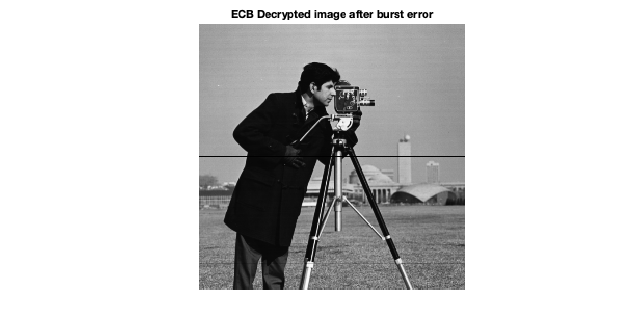

[~, height] = size(encrypted_image);
encrypted_image(height/2,:) = 0; % Clear middle line
decrypted_image = arrayfun(ecb_decrypt, encrypted_image);
imshow(decrypted_image,'InitialMagnification','fit');
title('ECB Decrypted image after burst error');

This error is clearly visible in the output, but only in the same position as in the ciphertext. This is because the decryption process does not depend on the values of adjacent blocks, so errors do not propagate.

However, ECB has a major issue. Since the value of every block only depends on the input value of every block, the structure of the image is clearly visible even in the encrypted output.

Here, (depending slightly on the random key that was chosen) we can see the outline of the photographer and the tripod, especially with basic filtering.

In addition, if an attacker knew the plaintext value of one pixel and its location, they could use this to decrypt all pixels with the same value, referred to as a **known plaintext attack**. An example of an easily determinable plaintext would be the color white or black in documents.

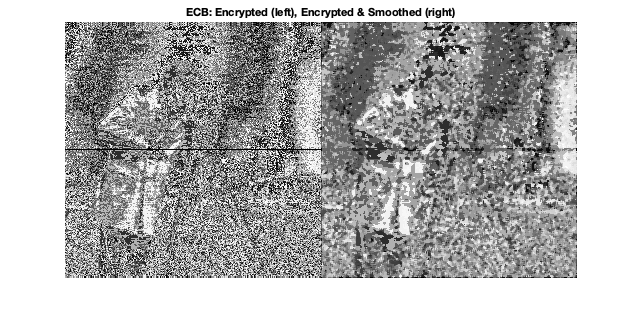

filtered_encrypted_image = medfilt2(bitand(encrypted_image,255)); %3x3 Median filter
imshowpair(bitand(encrypted_image,255), filtered_encrypted_image, ..., 
    'montage', 'Scaling','joint');
title('ECB: Encrypted (left), Encrypted & Smoothed (right)')

### Cipher Block Chaining (CBC)

In Cipher Block Chaining, we XOR the plaintext of each block with the previous ciphertext before encryption. The first block is XOR'd with an initialization vector, which should be randomly chosen in a real implementation to ensure **semantic security. **This property prevents an attacker from inferring mathematical relationships between different blocks, which could be combined with a known plaintext attack to decrypt adjacent blocks to the known plaintext.

Ciper Block Chaining is more complex to implement, as the message must be able to be padded to a multiple of the cipherblock size. In addition, as each block depends on the previous block, CBC cannot be performed in parallel. However, the chaining effect prevents an attacker from determining the structure of the image/plaintext, as will be shown below.

To speed computation, we use a short 10 bit key. Each pixel is 8 bits, but a key of exactly 8 bits was found to cause rounding issues with the powermod.m function used from the VPI library.

This is obviously a very short key and insecure, a more secure implementation would group several pixels into a larger block and use a larger key.

img = imread("cameraman.tif");
[Kp, Ks] = rsa_keygen(10); %9 bit key

Using a fixed initialisation vector (should be random in a real application)

iv = hex2dec('aa');

#### Encryption

Loop through, encrypting each pixel using CBC

[height, width] = size(img);
cbc_encrypted_image = zeros([height,width]);
last_block = uint8(iv);

for i=1:height
    for j=1:width
        % Get the block, 1 pixel per block
        block = uint8(img(i,j));
        % XOR with previous block
        block = bitxor(block, last_block, 'uint8');
        % Encrypt, sped up by calling VPI powermod directly
        encrypted_block = powermod(double(block), Kp.e, Kp.n); 
        % Save
        cbc_encrypted_image(i,j) = encrypted_block;
        last_block = bitand(encrypted_block,255);
    end
end

Now we corrupt our middle row, to compare against CBC

cbc_error_image = cbc_encrypted_image;
cbc_error_image(height/2,:) = 255;

#### Decryption

cbc_decrypted_image = zeros([height,width]);
last_block = uint8(iv);

for i=1:height
    for j=1:width
        encrypted_block = cbc_error_image(i,j);
        % Decrypt, have to cast to double to get correct result
        block = powermod(double(encrypted_block), Ks.d, Ks.n);
        
        % XOR again, undoing XOR done with encryption
        block = bitxor(bitand(block,255), last_block, 'uint8');

        % Save block to image, 1 pixel = 1 block
        cbc_decrypted_image(i,j) = block;
        
        % Save previous block for encryption
        last_block = bitand(encrypted_block,255);
    end
end

#### Results

Here is the output image with a burst error present on the middle line. Only the start of the next line is affected, which is the result of the "self syncronising" property of the CBC block cipher. When an error occurs in ciphertext block $C_{j\;}$, block $C_{j+1}$will not decrypt to the correct value, but blocks $C_{j+2}$ onwards are unaffected ([source](https://elec5616.com/static/lectures/2016/05_modes_of_operation.pdf), slide 10).

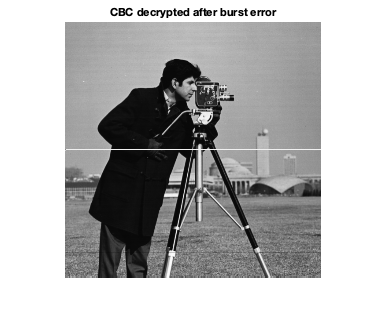

figure();
imshow(cbc_decrypted_image, [0 255]);
title('CBC decrypted after burst error');

Zooming in on the start of the next line, the error propagating to this first pixel (corresponding to $C_{j+1}$) can be seen more clearly:

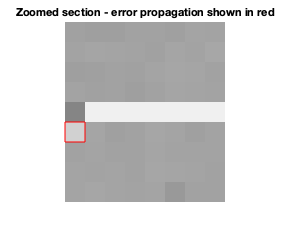

zoomed = cbc_decrypted_image(124:132, 1:8);
imshow(zoomed,[0,255],'initialMagnification',2000);
rectangle('Position',[0.5 5.5 1 1], "EdgeColor",'r'); %Highlight the error
title('Zoomed section - error propagation shown in red');

If we plot the **encrypted** image, there is now visible indication of the structure of the plaintext image, and instead the image resembles static. 

Therefore CBC offers a considerable increase in security, with the downside of slower processing that cannot be parallelised, and errors propagating to adjacent blocks. While in our example blocks are very small so this effect is not too visible, a practical implementation would use much larger blocks 

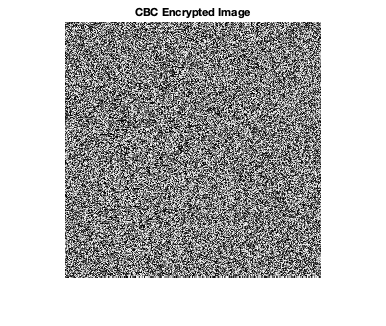

imshow(bitand(cbc_encrypted_image,255), [0,255]);
title('CBC Encrypted Image');